# Extract MFCC from Frequency-Domain Audio

Read in an audio file and convert it to a frequency representation.

[audioIn,fs] = audioread("Rainbow-16-8-mono-114secs.wav");

win = hann(1024,"periodic");
S = stft(audioIn,"Window",win,"OverlapLength",512,"Centered",false);

To extract the mel-frequency cepstral coefficients, call `mfcc` with the frequency-domain audio. Ignore the log-energy.

coeffs = mfcc(S,fs,"LogEnergy","Ignore");

In many applications, MFCC observations are converted to summary statistics for use in classification tasks. Plot a probability density function for one of the mel-frequency cepstral coefficients to observe its distributions.

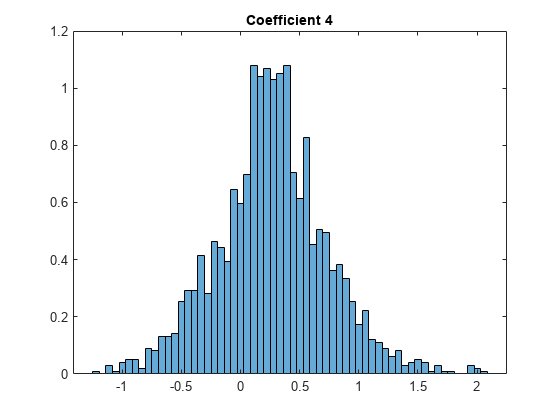

nbins = 60;
coefficientToAnalyze = 4;

histogram(coeffs(:,coefficientToAnalyze+1),nbins,"Normalization","pdf")
title(sprintf("Coefficient %d",coefficientToAnalyze))

*Copyright 2019 The MathWorks, Inc.*